# ** DEMO_02b:**   ***Alternate Derivation*** of Dynamic equations of motion of Slider crank mechanism

`Bradley Horton : 25-Feb-2022, bhorton@mathworks.com`

**Overview:**

- In this example we'll use **Newton's 2nd Law** to derive the Equations of motion for the slider crank mechanism shown below

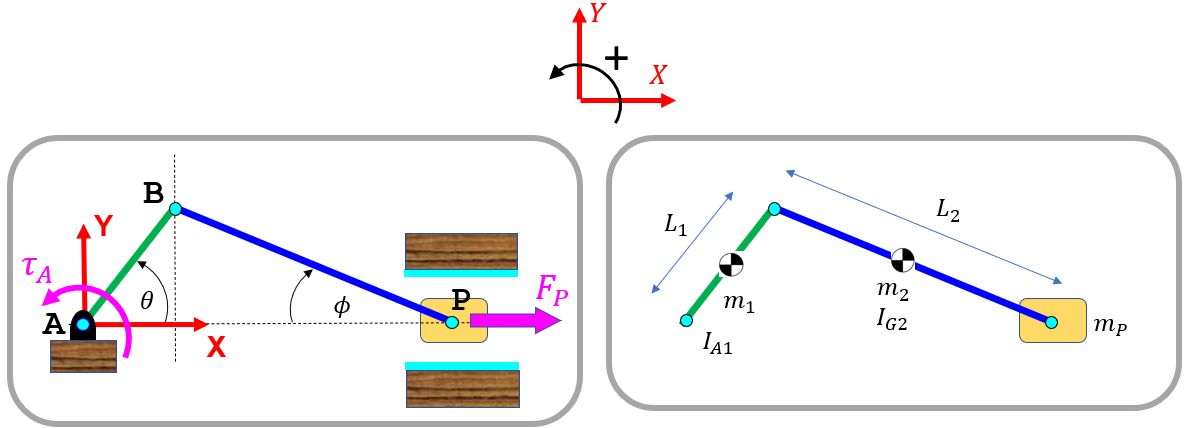

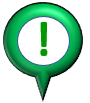 **NOTE: **

- Joint $A$ has viscous damping(friction)

- The piston head also experiences viscous damping(friction) as it slides 

- $b_A$ rotational viscous damping co-efficient at point A

- $b_P$ sliding viscous damping co-efficient acting on piston head

- $\tau_A$ an externally applied torque

- $F_P$ an externally applied force

- $L_1 \;,L_2$ are lengths of link AB and BP

- $m_1 \;,m_2$ are masses of link AB and BP

- $m_P$ is the mass of the piston head

- $I_{\textrm{A1}}$ is the inertia of link AB about pivot point A

- $I_{\textrm{G2}}$ is the inertia of link BP about its centre of mass

## Configure our Symbolic computing session:

Let's disable the preference that shows our output in abbreviated form, ie: when we display our symbolic expressions it won't use auxillary symbols to shorten the displayed output. 

- RELAX - that's just alot of words for saying we want to see the output displayed in it's most RAW form

sympref('AbbreviateOutput',false);

## Kinematic Analysis:

To derive the dynamic equations of motion we'll be applying Newton's $2^{\textrm{nd}}$ Law, ie:

- $m_G \ldotp a\;=\;\sum F$    and    $I_G \ldotp \ddot{\theta} \;=\;$$\sum M_Z \;$

So ? - So very soon we'll need expressions for the ***accelerations of the center of masses*** of each mass in our machine.

So first, let's establish some kinematic relationships for the position, velocity and accelerations of the center of masses for each mass:

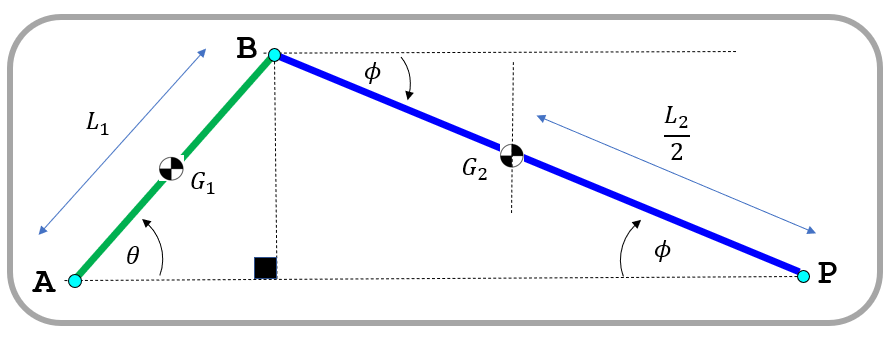

syms  theta   theta_dot  theta_ddot
syms  phi     phi_dot    phi_ddot
syms  L_1     L_2  

Acceleration of **GREEN link CoM**

- 
$$\left\lbrack \begin{array}{c}
x_{\textrm{G1}} \\
y_{\textrm{G1}} 
\end{array}\right\rbrack \;\;\;\;\;=\left\lbrack \begin{array}{c}
\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\\
\frac{L_1 }{2}\ldotp \sin \left(\theta \right)
\end{array}\right\rbrack$$


- 
$$\left\lbrack \begin{array}{c}
v_{\textrm{XG1}} \\
v_{\textrm{YG1}} 
\end{array}\right\rbrack \;\;=\left\lbrack \begin{array}{c}
-\frac{L_1 }{2}\ldotp \sin \left(\theta \right)\ldotp \dot{\theta} \\
\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\ldotp \dot{\theta} 
\end{array}\right\rbrack$$


- $\left\lbrack \begin{array}{c}
a_{\textrm{XG1}} \\
a_{\textrm{YG1}} 
\end{array}\right\rbrack \;\;=\left\lbrack \begin{array}{c}
-\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\ldotp {\dot{\theta} }^2 \;\;+\;\;-\frac{L_1 }{2}\ldotp \sin \left(\theta \right)\ldotp \ddot{\theta} \\
-\frac{L_1 }{2}\ldotp \sin \left(\theta \right)\ldotp {\dot{\theta} }^2 \;\;+\;\;\;\;\;\frac{L_1 }{2}\ldotp \cos \left(\theta \right)\ldotp \ddot{\theta} 
\end{array}\right\rbrack$ ................    **EQ_1**

a_G1  =  [ (  (-L_1/2)*cos(theta)*theta_dot^2  +  (-L_1/2)*sin(theta)*theta_ddot  );
           (  (-L_1/2)*sin(theta)*theta_dot^2  +  ( L_1/2)*cos(theta)*theta_ddot  );   ]

$$a\_G1 = \left(\begin{array}{c} -\frac{L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}}{2}-\frac{L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)}{2}\\ \frac{L_{1}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}-\frac{L_{1}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{2} \end{array}\right)$$

Acceleration of **BLUE link CoM**

- 
$$\left\lbrack \begin{array}{c}
x_{\textrm{G2}} \\
y_{\textrm{G2}} 
\end{array}\right\rbrack \;\;\;=\;\;\left\lbrack \begin{array}{c}
L_1 \ldotp \cos \left(\theta \right)\\
L_1 \ldotp \sin \left(\theta \right)
\end{array}\right\rbrack \;+\left\lbrack \begin{array}{c}
\;\;\;\frac{L_2 }{2}\ldotp \cos \left(\phi \right)\\
-\frac{L_2 }{2}\ldotp \sin \left(\phi \right)
\end{array}\right\rbrack \;$$


-               
$$=\;2\ldotp \left\lbrack \begin{array}{c}
x_{\textrm{G1}} \\
y_{\textrm{G1}} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;+\;\left\lbrack \begin{array}{c}
\;\;\;\frac{L_2 }{2}\ldotp \cos \left(\phi \right)\\
-\frac{L_2 }{2}\ldotp \sin \left(\phi \right)
\end{array}\right\rbrack$$

$$\;\;$$


- 
$$\left\lbrack \begin{array}{c}
v_{\textrm{G2}} \\
v_{\textrm{G2}} 
\end{array}\right\rbrack \;\;\;\;=\;2\ldotp \left\lbrack \begin{array}{c}
v_{\textrm{XG1}} \\
v_{\textrm{YG1}} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;+\left\lbrack \begin{array}{c}
-\frac{L_2 }{2}\ldotp \sin \left(\phi \right)\ldotp \dot{\phi} \\
-\frac{L_2 }{2}\ldotp \cos \left(\phi \right)\ldotp \dot{\phi} 
\end{array}\right\rbrack \;\;$$


- $\left\lbrack \begin{array}{c}
a_{\textrm{G2}} \\
a_{\textrm{G2}} 
\end{array}\right\rbrack \;\;\;\;=\;2\ldotp \left\lbrack \begin{array}{c}
a_{\textrm{XG1}} \\
a_{\textrm{YG1}} 
\end{array}\right\rbrack \;\;\;\;\;\;\;\;+\left\lbrack \begin{array}{c}
-\frac{L_2 }{2}\ldotp \cos \left(\phi \right)\ldotp {\dot{\phi} }^2 \;\;\;\;+\;\;-\frac{L_2 }{2}\ldotp \sin \left(\phi \right)\ldotp \ddot{\phi} \\
\;\;\;\frac{L_2 }{2}\ldotp \sin \left(\phi \right)\ldotp {\dot{\phi} }^2 \;\;\;\;\;+\;\;-\frac{L_2 }{2}\ldotp \cos \left(\phi \right)\ldotp \ddot{\phi} 
\end{array}\right\rbrack \;\;$ ................    **EQ_2**

a_G2  =    2*a_G1  +    [ (  (-L_2/2)*cos(phi)*phi_dot^2  +  (-L_2/2)*sin(phi)*phi_ddot  );
                           (  ( L_2/2)*sin(phi)*phi_dot^2  +  (-L_2/2)*cos(phi)*phi_ddot  );   ]

$$a\_G2 = \left(\begin{array}{c} -\frac{L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}}{2}-L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}-\frac{L_{2}\,\ddot{\varphi }\,\sin\left(\varphi \right)}{2}-L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)\\ \frac{L_{2}\,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}}{2}-L_{1}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\frac{L_{2}\,\ddot{\varphi }\,\cos\left(\varphi \right)}{2}+L_{1}\,\ddot{\theta }\,\cos\left(\theta \right) \end{array}\right)$$

Acceleration of **point P CoM**

- 
$$x_P \;\;=\;\;\;\;\;\;L_1 \ldotp \cos \left(\theta \right)\;\;\;\;\;+\;\;\;\;\;\;L_2 \ldotp \cos \left(\phi \right)$$


- 
$$v_P \;\;=\;\;{-L}_1 \ldotp \sin \left(\theta \right)\ldotp \dot{\theta} \;\;+\;-L_2 \ldotp \sin \left(\phi \right)\ldotp \dot{\phi}$$


- $a_P \;\;=\;\left({-L}_1 \ldotp \cos \left(\theta \right)\ldotp {\dot{\theta} }^2 \;\;\;\;+\;\;{-L}_1 \ldotp \sin \left(\theta \right)\ldotp \ddot{\theta} \right)\;\;+\left(-L_2 \ldotp \cos \left(\phi \right)\ldotp {\dot{\phi} }^2 \;\;+\;-L_2 \ldotp \sin \left(\phi \right)\ldotp \ddot{\phi} \right)$   ................    **EQ_3**

v_P =   -L_1*sin(theta)*theta_dot  - L_2*sin(phi)*phi_dot  % need this for the damping Force

$$v\_P = -L_{2}\,\dot{\varphi }\,\sin\left(\varphi \right)-L_{1}\,\dot{\theta }\,\sin\left(\theta \right)$$


a_P =   (-L_1*cos(theta)*theta_dot^2   + -L_1*sin(theta)*theta_ddot)   +   ...
        (-L_2*cos(phi)*phi_dot^2       + -L_2*sin(phi)*phi_ddot)

$$a\_P = -L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}-L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}-L_{2}\,\ddot{\varphi }\,\sin\left(\varphi \right)-L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)$$

### The constraint relationship:

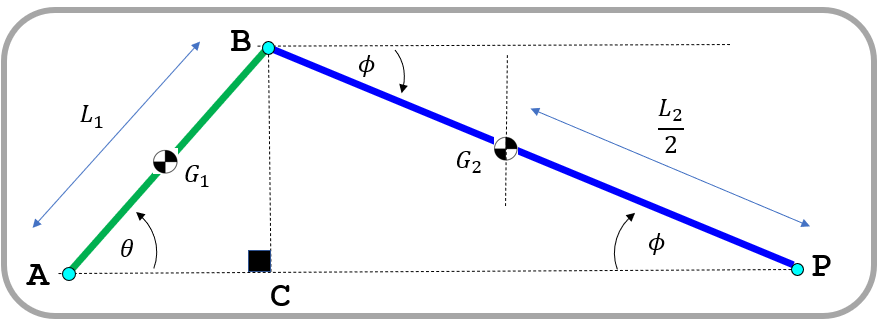

Recall also the constraint that binds $\theta$ and $\phi$:

- 
$$\;\;\;\;\;\;\;\;\;\;\;\textrm{BC}\;\;\;=\;\;\;\textrm{BC}$$


- $L_1 \ldotp \sin \left(\theta \right)\;\;=\;\;L_2 \ldotp \sin \left(\phi \right)$         ................    **EQ_4**

Which we can differentiate once and twice ***w.r.t time*** to give the relationships:

- $L_1 \ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;\;=\;\;L_2 \ldotp \cos \left(\phi \right)\ldotp \dot{\phi}$                     ................    **EQ_5**

- $-L_1 \ldotp \sin \left(\theta \right)\ldotp {\dot{\theta} }^2 \;\;+\;L_1 \ldotp \cos \left(\theta \right)\ldotp \ddot{\theta} \;\;\;=\;\;{-L}_2 \ldotp \sin \left(\phi \right)\ldotp {\dot{\phi} }^2 \;\;+\;L_2 \ldotp \cos \left(\phi \right)\ldotp \ddot{\phi}$         ................    **EQ_6**

 **NOTE:** 

- EQ_4 gives us an expression for $\sin \left(\phi \right)$ as a $f\left(\theta \right)$

- EQ_4 also allows us to write an expression for $\cos \left(\phi \right)$ as a $h\left(\theta \right)$ .... eg:  $\cos \left(\phi \right)=\sqrt{1\;\;-\;\sin^2 \left(\phi \right)}$

- EQ_5 gives us an expression for $\dot{\phi}$ as a $f\left(\theta ,\cos \left(\phi \right),\dot{\theta} \right)$

- EQ_6 gives us an expression for $\ddot{\phi}$ as a $f\left(\theta ,\cos \left(\phi \right),\sin \left(\phi \right),\dot{\theta} ,\dot{\phi} \right)$

## Dynamic Analysis:

Next let's draw our Free Body diagrams and apply Newton's $2^{\textrm{nd}}$ Law

 **ASSUMPTIONS: **

- Joint $A$ has viscous damping(friction)

- The piston head also experiences viscous damping(friction) as it slides 

syms  m_1     m_2  m_P   I_A1  I_G2
syms  b_A     b_P
syms  R_AX    R_AY   R_BX   R_BY   R_PX  R_PY
syms  g       tau_A  F_P
syms  N_P

Here's the **Free Body Diagram**(FBD) for the 3 inertias of our system

-  **ATTENTION:**  See `Appendix_A` for a more detailed discussion on the Free Body diagram for the ORANGE piston

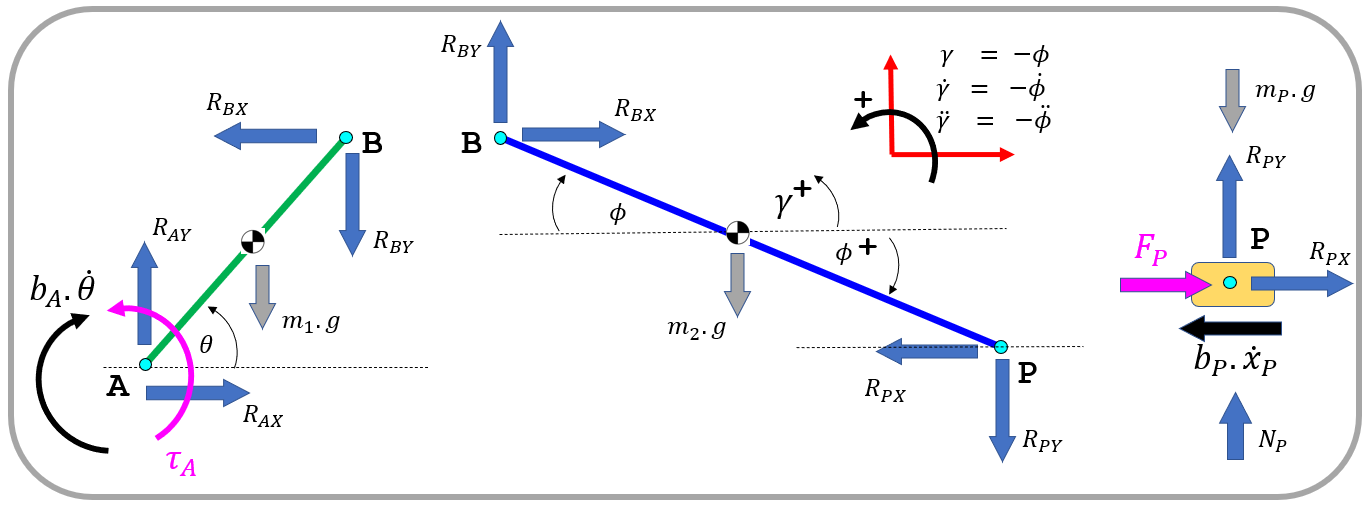

### **Applying Newton's 2nd Law to the GREEN link**

Summing the forces in the $X$and $Y$directions gives us:

- 
$$m_1 \ldotp {\ddot{x} }_{1G} \;\;=\;\sum F_X \;=R_{\textrm{AX}\;} \;\;-\;R_{\textrm{BX}}$$


- 
$$m_1 \ldotp {\ddot{y} }_{1G} \;\;=\;\sum F_Y \;=R_{\textrm{AY}} \;-m_1 \ldotp g\;\;-\;R_{\textrm{BY}}$$
 

EQ_X_1 = m_1*a_G1(1) == R_AX - R_BX;
EQ_Y_1 = m_1*a_G1(2) == R_AY - m_1*g - R_BY;

Taking the sum of the torques about the ***pivot point A***:

- 
$$I_{\textrm{A1}} \ldotp \ddot{\theta} \;=\;$$

$$\sum M_Z \;\;=\tau_A \;-b_A \ldotp \dot{\theta} \;-m_1 \ldotp g\ldotp \frac{L_1 }{2}\ldotp \cos \left(\theta \right)-R_{\textrm{BY}} \ldotp L_1 \ldotp \cos \left(\theta \right)\;+\;\;R_{\textrm{BX}} \ldotp L_1 \ldotp \sin \left(\theta \right)\;$$


EQ_M_1 = I_A1*theta_ddot ==  tau_A  -  b_A*theta_dot - m_1*g*cos(theta)*L_1/2  ...
                             - R_BY*L_1*cos(theta)  +   R_BX*L_1*sin(theta)

$$EQ\_M\_1 = I_{\mathrm{A1}}\,\ddot{\theta }=\tau_{A}-b_{A}\,\dot{\theta }-L_{1}\,R_{\mathrm{BY}}\,\cos\left(\theta \right)+L_{1}\,R_{\mathrm{BX}}\,\sin\left(\theta \right)-\frac{L_{1}\,g\,m_{1}\,\cos\left(\theta \right)}{2}$$

### **Applying Newton's 2nd Law to the BLUE link**

Summing the forces in the $X$and $Y$directions gives us:

- 
$$m_2 \ldotp {\ddot{x} }_{2G} \;\;=\;\sum F_X \;=R_{\textrm{BX}\;} \;\;-\;R_{\textrm{PX}}$$


- 
$$m_2 \ldotp {\ddot{y} }_{2G} \;\;=\;\sum F_Y \;=R_{\textrm{BY}} \;-m_2 \ldotp g\;\;-\;R_{\textrm{PY}}$$
 

EQ_X_2 = m_2*a_G2(1) == R_BX - R_PX;
EQ_Y_2 = m_2*a_G2(2) == R_BY - m_2*g - R_PY;

Taking the sum of the torques about the ***center of mass point ***$G_2$:

- 
$$I_{\textrm{G2}} \ldotp \ddot{\gamma} \;=\;$$

$$\sum M_Z \;\;=\;\;-1\ldotp \left(R_{\textrm{BY}} \ldotp \cos \left(\phi \right)\ldotp \frac{L_2 }{2}\;\;+\;\;R_{\textrm{BX}} \ldotp \sin \left(\phi \right)\ldotp \frac{L_2 }{2}\;\;+\;\;R_{\textrm{PY}} \ldotp \cos \left(\phi \right)\ldotp \frac{L_2 }{2}\;\;+\;R_{\textrm{PX}} \ldotp \sin \left(\phi \right)\ldotp \frac{L_2 }{2}\right)\;$$


 **NOTE:**     $\ddot{\gamma} \;=\;-\ddot{\phi}$

EQ_M_2 = I_G2*(-phi_ddot) ==  -1*(   R_BY*cos(phi)*L_2/2  +   R_BX*sin(phi)*L_2/2   ...
                                   + R_PY*cos(phi)*L_2/2  +   R_PX*sin(phi)*L_2/2     )

$$EQ\_M\_2 = -I_{\mathrm{G2}}\,\ddot{\varphi }=-\frac{L_{2}\,R_{\mathrm{BY}}\,\cos\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{PY}}\,\cos\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{BX}}\,\sin\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{PX}}\,\sin\left(\varphi \right)}{2}$$

### **Applying Newton's 2nd Law to ORANGE piston**

 **ATTENTION:**  See `Appendix_A` for a more detailed discussion on the Free Body diagram for the ORANGE piston

Summing the forces in the $X$and $Y$directions gives us:

- 
$$m_P \ldotp {\ddot{x} }_P \;\;\;\;\;\;\;\;\;\;\;=\;\sum F_X \;={\;\;F_P \;\;\;+\;\;\;R}_{\textrm{PX}\;} \;\;-b_P \ldotp {\dot{x} }_P$$


- 
$$m_P \ldotp {\ddot{y} }_P \;\;=0=\;\;\sum F_Y \;={\;\;N_P \;\;\;+\;\;\;R}_{\textrm{PY}\;} \;\;-m_P \ldotp g$$


EQ_X_3 = m_P*a_P == F_P + R_PX - b_P*v_P

$$EQ\_X\_3 = -m_{P}\,\left(L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}+L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+L_{2}\,\ddot{\varphi }\,\sin\left(\varphi \right)+L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)\right)=F_{P}+R_{\mathrm{PX}}+b_{P}\,\left(L_{2}\,\dot{\varphi }\,\sin\left(\varphi \right)+L_{1}\,\dot{\theta }\,\sin\left(\theta \right)\right)$$

EQ_Y_3 =       0 == N_P + R_PY - m_P*g

$$EQ\_Y\_3 = 0=N_{P}+R_{\mathrm{PY}}-g\,m_{P}$$

### Summary so far

So let's collect our 8 equations:

EQ_SYS = [  EQ_X_1;
            EQ_Y_1; 
            EQ_M_1;
            EQ_X_2;
            EQ_Y_2; 
            EQ_M_2;
            EQ_X_3;
            EQ_Y_3 ]

$$EQ\_SYS = \left(\begin{array}{c} -m_{1}\,\left(\frac{L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}}{2}+\frac{L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)}{2}\right)=R_{\mathrm{AX}}-R_{\mathrm{BX}}\\ -m_{1}\,\left(\frac{L_{1}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{2}-\frac{L_{1}\,\ddot{\theta }\,\cos\left(\theta \right)}{2}\right)=R_{\mathrm{AY}}-R_{\mathrm{BY}}-g\,m_{1}\\ I_{\mathrm{A1}}\,\ddot{\theta }=\tau_{A}-b_{A}\,\dot{\theta }-L_{1}\,R_{\mathrm{BY}}\,\cos\left(\theta \right)+L_{1}\,R_{\mathrm{BX}}\,\sin\left(\theta \right)-\frac{L_{1}\,g\,m_{1}\,\cos\left(\theta \right)}{2}\\ -m_{2}\,\left(\frac{L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}}{2}+L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+\frac{L_{2}\,\ddot{\varphi }\,\sin\left(\varphi \right)}{2}+L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)\right)=R_{\mathrm{BX}}-R_{\mathrm{PX}}\\ m_{2}\,\left(\frac{L_{2}\,\sin\left(\varphi \right)\,{\dot{\varphi }}^{2}}{2}-L_{1}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-\frac{L_{2}\,\ddot{\varphi }\,\cos\left(\varphi \right)}{2}+L_{1}\,\ddot{\theta }\,\cos\left(\theta \right)\right)=R_{\mathrm{BY}}-R_{\mathrm{PY}}-g\,m_{2}\\ -I_{\mathrm{G2}}\,\ddot{\varphi }=-\frac{L_{2}\,R_{\mathrm{BY}}\,\cos\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{PY}}\,\cos\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{BX}}\,\sin\left(\varphi \right)}{2}-\frac{L_{2}\,R_{\mathrm{PX}}\,\sin\left(\varphi \right)}{2}\\ -m_{P}\,\left(L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}+L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}+L_{2}\,\ddot{\varphi }\,\sin\left(\varphi \right)+L_{1}\,\ddot{\theta }\,\sin\left(\theta \right)\right)=F_{P}+R_{\mathrm{PX}}+b_{P}\,\left(L_{2}\,\dot{\varphi }\,\sin\left(\varphi \right)+L_{1}\,\dot{\theta }\,\sin\left(\theta \right)\right)\\ 0=N_{P}+R_{\mathrm{PY}}-g\,m_{P} \end{array}\right)$$

 So How many unknowns do we have ?   Well we actually have 9 unknowns:

- 
$$R_{\textrm{AX}} \;,\;$$

$$R_{\textrm{AY}}$$


- 
$$R_{\textrm{BX}} \;,\;$$

$$R_{\textrm{BY}}$$


- 
$$R_{\textrm{PX}} \;,\;$$

$$R_{\textrm{PY}}$$


- 
$$N_P$$


- 
$$\ddot{\theta} ,\;\;\;\;\ddot{\phi}$$


So we have $7$ unknown reaction forces and 2 unknown accelerations.

**Pause and Ponder:**

- we have 8 equations .... with 9 unknowns

- What about our holonomic constraint ? - can we use that ... somehow ? 

### Enforce our Holonomic constraint:

 Recall the relationship between $\theta$ and $\phi$, :

- 
$$\;\;\;\;\;\;\;\;\;\;\;\textrm{BC}\;\;\;=\;\;\;\textrm{BC}$$


- 
$$L_1 \ldotp \sin \left(\theta \right)\;\;=\;\;L_2 \ldotp \sin \left(\phi \right)$$


And we can differentiate the above constraint ***w.r.t time*** once and twice:

- 
$$L_1 \ldotp \cos \left(\theta \right)\ldotp \dot{\theta} \;\;=\;\;L_2 \ldotp \cos \left(\phi \right)\ldotp \dot{\phi}$$


- $-L_1 \ldotp \sin \left(\theta \right)\ldotp {\dot{\theta} }^2 \;\;+\;L_1 \ldotp \cos \left(\theta \right)\ldotp \ddot{\theta} \;\;\;=\;\;{-L}_2 \ldotp \sin \left(\phi \right)\ldotp {\dot{\phi} }^2 \;\;+\;L_2 \ldotp \cos \left(\phi \right)\ldotp \ddot{\phi}$  .....  **EQ_A**

So **EQ_A** gives us our $9^{\textrm{th}}$ equation without introducing any additional unknowns.

EQ_9 = (-L_1*sin(theta)*(theta_dot^2) + L_1*cos(theta)*theta_ddot) == ...
       (-L_2*sin(phi)*(phi_dot^2)     + L_2*cos(phi)*phi_ddot);

So now our system of equations is:

EQ_SYS = [ EQ_SYS;
           EQ_9 ]

 So we now have 9 equations with 9** unknowns**:

- 
$$\left\lbrack \begin{array}{ccccccccc}
\ddot{\theta}  & \ddot{\phi}  & R_{\textrm{AX}}  & R_{\textrm{AY}}  & R_{\textrm{BX}}  & R_{\textrm{BY}}  & R_{\textrm{PX}}  & R_{\textrm{PY}}  & N_P 
\end{array}\right\rbrack$$


When you examine these 9 equations, note how the unknowns $\left\lbrack \begin{array}{ccccccccc}
\ddot{\theta}  & \ddot{\phi}  & R_{\textrm{AX}}  & R_{\textrm{AY}}  & R_{\textrm{BX}}  & R_{\textrm{BY}}  & R_{\textrm{PX}}  & R_{\textrm{PY}}  & N_P 
\end{array}\right\rbrack$ all appear as **linear terms**,  e.g.:  $\ddot{\theta} \times \textrm{something}$,  $R_{\textrm{AY}} \times \textrm{someOtherThing}$.  So? - So because these 9 unknowns appear as **linear terms**, we can compute them by simply solving a system of 8 simultaneous equations.  Conceptually this is an easy task to do and with enough time and patience you could do this by hand.  However today we'll get MATLAB to do this for us.  Specifically we're going to get MATLAB's function  [`equationsToMatrix`](matlab:  web(fullfile(docroot, 'symbolic/sym.equationstomatrix.html'))) to rearrange our 8 equations into the following shape:

- $A\ldotp x=b$     where    $x\;={\left\lbrack \begin{array}{ccccccccc}
\ddot{\theta}  & \ddot{\phi}  & R_{\textrm{AX}}  & R_{\textrm{AY}}  & R_{\textrm{BX}}  & R_{\textrm{BY}}  & R_{\textrm{PX}}  & R_{\textrm{PY}}  & N_P 
\end{array}\right\rbrack }^{\;T}$

## Reshape our system of ODEs

So Let's convert our system of ODEs into the form:

- $A\ldotp x=b$     where    $x\;={\left\lbrack \begin{array}{ccccccccc}
\ddot{\theta}  & \ddot{\phi}  & R_{\textrm{AX}}  & R_{\textrm{AY}}  & R_{\textrm{BX}}  & R_{\textrm{BY}}  & R_{\textrm{PX}}  & R_{\textrm{PY}}  & N_P 
\end{array}\right\rbrack }^{\;T}$

 **ATTENTION:** we're doing this because once we have the $A,b$ matrices we can then use them to NUMERICALLY solve the dynamic system in **Simulink.**

sys_x           = [theta_ddot, phi_ddot,    R_AX, R_AY,   R_BX, R_BY,   R_PX, R_PY,   N_P].' ;
[sys_A, sys_b]  = equationsToMatrix(EQ_SYS, sys_x) 

$$sys\_A = \left(\begin{array}{ccccccccc} -\frac{L_{1}\,m_{1}\,\sin\left(\theta \right)}{2} & 0 & -1 & 0 & 1 & 0 & 0 & 0 & 0\\ \frac{L_{1}\,m_{1}\,\cos\left(\theta \right)}{2} & 0 & 0 & -1 & 0 & 1 & 0 & 0 & 0\\ I_{\mathrm{A1}} & 0 & 0 & 0 & -L_{1}\,\sin\left(\theta \right) & L_{1}\,\cos\left(\theta \right) & 0 & 0 & 0\\ -L_{1}\,m_{2}\,\sin\left(\theta \right) & -\frac{L_{2}\,m_{2}\,\sin\left(\varphi \right)}{2} & 0 & 0 & -1 & 0 & 1 & 0 & 0\\ L_{1}\,m_{2}\,\cos\left(\theta \right) & -\frac{L_{2}\,m_{2}\,\cos\left(\varphi \right)}{2} & 0 & 0 & 0 & -1 & 0 & 1 & 0\\ 0 & -I_{\mathrm{G2}} & 0 & 0 & \frac{L_{2}\,\sin\left(\varphi \right)}{2} & \frac{L_{2}\,\cos\left(\varphi \right)}{2} & \frac{L_{2}\,\sin\left(\varphi \right)}{2} & \frac{L_{2}\,\cos\left(\varphi \right)}{2} & 0\\ -L_{1}\,m_{P}\,\sin\left(\theta \right) & -L_{2}\,m_{P}\,\sin\left(\varphi \right) & 0 & 0 & 0 & 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & -1 & -1\\ L_{1}\,\cos\left(\theta \right) & -L_{2}\,\cos\left(\varphi \right) & 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

$$sys\_b = \left(\begin{array}{c} \frac{L_{1}\,m_{1}\,{\dot{\theta }}^{2}\,\cos\left(\theta \right)}{2}\\ \frac{L_{1}\,m_{1}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)}{2}-g\,m_{1}\\ \tau_{A}-b_{A}\,\dot{\theta }-\frac{L_{1}\,g\,m_{1}\,\cos\left(\theta \right)}{2}\\ m_{2}\,\left(\frac{L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}}{2}+L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}\right)\\ -g\,m_{2}-m_{2}\,\left(\frac{L_{2}\,{\dot{\varphi }}^{2}\,\sin\left(\varphi \right)}{2}-L_{1}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)\right)\\ 0\\ F_{P}+b_{P}\,\left(L_{2}\,\dot{\varphi }\,\sin\left(\varphi \right)+L_{1}\,\dot{\theta }\,\sin\left(\theta \right)\right)+m_{P}\,\left(L_{2}\,\cos\left(\varphi \right)\,{\dot{\varphi }}^{2}+L_{1}\,\cos\left(\theta \right)\,{\dot{\theta }}^{2}\right)\\ -g\,m_{P}\\ L_{1}\,{\dot{\theta }}^{2}\,\sin\left(\theta \right)-L_{2}\,{\dot{\varphi }}^{2}\,\sin\left(\varphi \right) \end{array}\right)$$

## Convert this to a Simulink block:

Awesome !  Now that we have these $A,b$ matrices let's convert them into Simulink blocks so that we can numerically solve the ODEs.

tf_i_should_create_SL_block = true;

OK, let's do it:

if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_slider_crank';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
        
    %-------------------------------------------------------
    % Create a block that computes A and b
    matlabFunctionBlock( [MODEL_NAME,'/my_EOM'], ...
                         sys_A, ...
                         sys_b, ...
                        "Outputs", {'A','b'}  )
                    
    % make the block a YELLOW color
    set_param([MODEL_NAME,'/my_EOM'],'BackgroundColor','[1, 1, 0.607843]')
end

The little yellow Simulink block now contains the MATLAB code that computes the $A$ and $b$ matrices,

# Next Steps:

Now that we've got our Mechanical Equations of motion, let's numerically solve them in Simulink.

Open and run the script file [`bh_DEMO_03_dynamics_simulation_SLIDER_CRANK`](matlab:  edit bh_DEMO_03_dynamics_simulation_SLIDER_CRANK) to explore this next step.

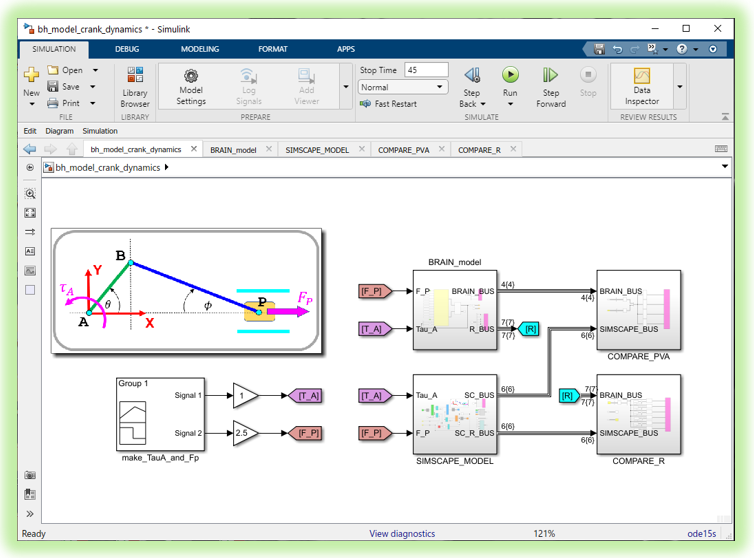                  

# **Appendix A:**      A closer look at the FBD of the Piston

Consider the Free Body Diagram of just the piston:

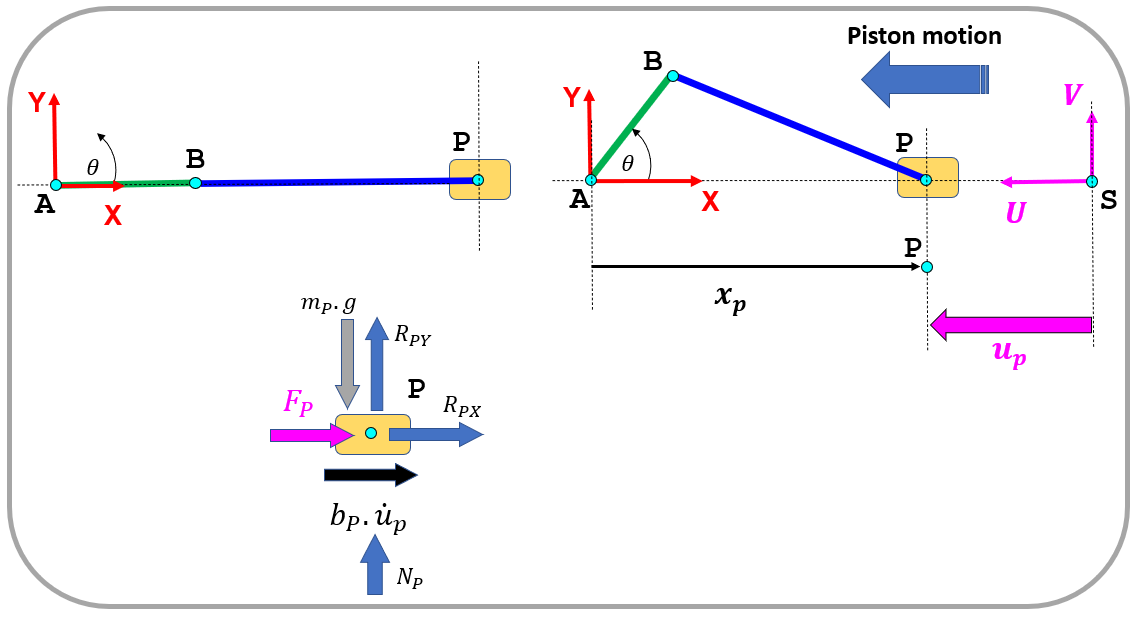 

In the diagram above we have 2 inertial frames - one with origin at point $A$ and the other with origin at point $S$.  The horizontal position of point $P$ can be described by:

- 
$$\textrm{AB}\;\;+\;\;\textrm{BP}\;\;=\;\;x_P \;\;+\;\;u_P$$


-      
$$\textrm{constant}\;\;=\;\;x_P \;\;+\;\;u_P$$


And differentiating both sides ***w.r.t  time***, we get:

- 
$$0\;\;=\;\;{\dot{x} }_P \;\;+\;\;{\dot{u} }_P$$


- 
$$0\;\;=\;\;{\ddot{x} }_P \;\;+\;\;{\ddot{u} }_P$$


Now applying Newton's $2^{\textrm{nd}}$ law in the horizontal direction according to the Inertial frame at point $S$, we get:

- 
$$m_2 \ldotp {\ddot{u} }_P \;\;=\;\sum F_U \;\;=\;\;\;{-F_P \;\;\;-R}_{\textrm{PX}\;} \;\;-b_P \ldotp {\dot{u} }_P$$


Now substitute in $\left(\;{\dot{u} }_P \;=\;-{\dot{x} }_P \;\right)$ and $\left(\;\;{\ddot{u} }_P \;\;=\;\;-{\ddot{x} }_P \right)$ we get:

- 
$$m_2 \ldotp \left(-{\ddot{x} }_P \right)\;\;=\;\;\;\;{-F_P \;\;\;-R}_{\textrm{PX}\;} \;\;-b_P \ldotp \left(-{\dot{x} }_P \right)$$


which can be re-arranged to give:

- 
$$m_2 \ldotp {\ddot{x} }_P \;\;=\;\;\;\;{F_P \;\;\;\;+\;\;R}_{\textrm{PX}\;} \;\;-b_P \ldotp \left({\dot{x} }_P \right)$$


This equation of motion is identical to the one that we would get if we "assumed" that the pistion was travelling in the $+^{\prime } \textrm{ve}$ $X$ direction and drawn the subsequent FBD for that scenario ... and then written Newton's $2^{\textrm{nd}}$law using teh inertial reference frame at point $A,$ eg:

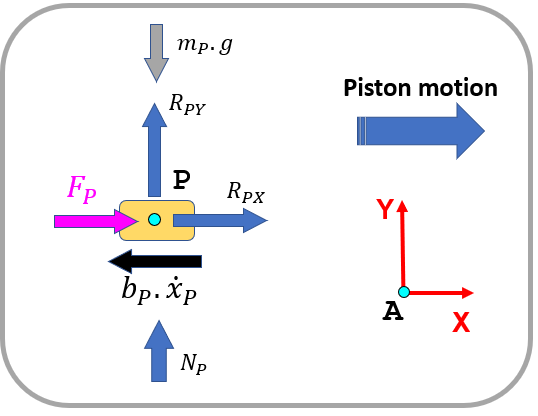

OK, let's get back to the main analysis - `click ME` .